# Plots in introductory figures

## load and preprocess data

% load from PopTiming
load('Spikes.mat');
load('N-30.mat');

nparams = size(c,1); % number of sets of firing rate parameters
ntrials = size(c,2)-5; % number of trials

RT = zeros(nparams, ntrials);
for i = 1:nparams
    for j = 1:ntrials
        RT(i,j) = c{i,j}.performance(1,3);
    end
end

params = c(:,ntrials+1:ntrials+5);
params = cell2mat(params);
lambda1 = params(:,1);
k1 = params(:,3);
fr = params(:,5);
fr = round(fr,-1);
burstiness = k1./lambda1;
RT = median(RT,2);

## tonic and bursty cell rasters

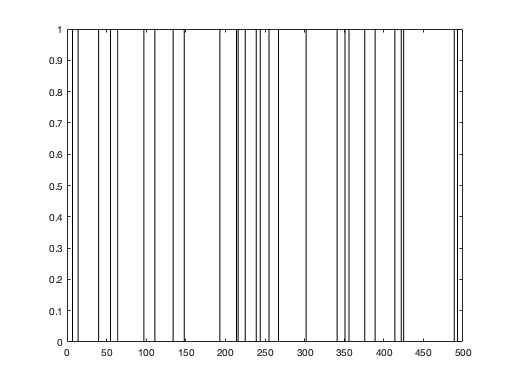

% constant firing rate of 100 Hz
fr_row = find(fr==100); 
[burstmin, min_ind] = min(burstiness(fr_row,:),[],'all','linear'); 
[burstmax, max_ind] = max(burstiness(fr_row,:),[],'all','linear'); 

% take first cell in population
allspikes = Spikes{fr_row(min_ind)};
spikes = allspikes(:,1);
spike_ind = find(spikes(1800:2300));

figure;
for i = 1:length(spike_ind) % index over spike times in trial j
    plot([spike_ind(i) spike_ind(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

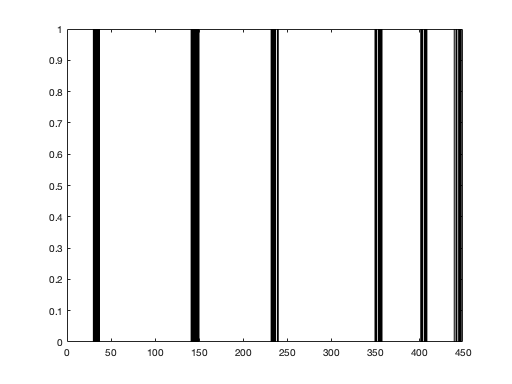


% take first cell in population
allspikes = Spikes{fr_row(max_ind)};
spikes = allspikes(:,1);
spike_ind = find(spikes(1500:2000));

figure;
for i = 1:length(spike_ind) % index over spike times in trial j
    plot([spike_ind(i) spike_ind(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

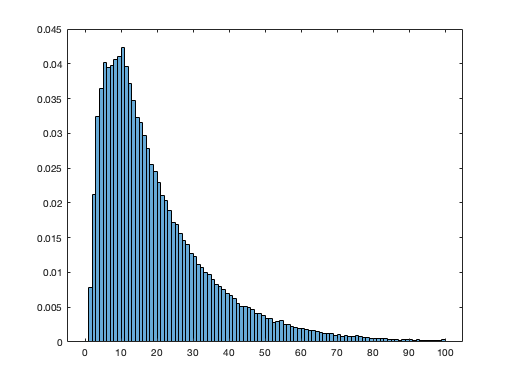

% example burstiness ISI histograms
% constant firing rate of 100 Hz
fr_row = find(fr==100); 
min_ind = find(burstiness(fr_row)==0.01,1);
mid_ind = find(burstiness(fr_row)==0.03,1);
max_ind = find(burstiness(fr_row)==0.1);

% make ISI histogram with all cells, all trials
allspikes = Spikes(fr_row(min_ind),:);
spike_ind = [];
for i = 1:ntrials
    newspikes = allspikes{1,i};
    for j = 1:30
        newspike_ind = find(newspikes(:,j));
        spike_ind = [spike_ind; newspike_ind];
    end
end
isi_tonic = diff(spike_ind);
isi_tonic = isi_tonic(isi_tonic>0);
edge_tonic = 0:100;
histogram(isi_tonic,edge_tonic,'Normalization','pdf')

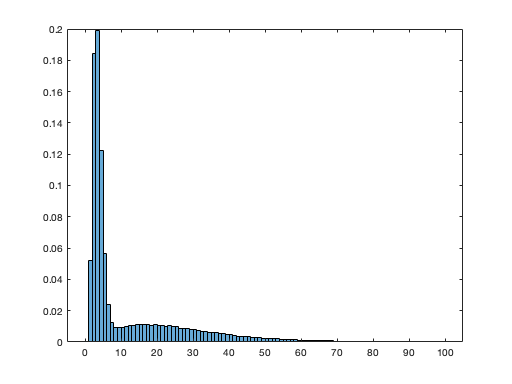

[h_isi_tonic] = histcounts(isi_tonic,edge_tonic,'Normalization','pdf');

% make ISI histogram with all cells, all trials
allspikes = Spikes(fr_row(mid_ind),:);
spike_ind = [];
for i = 1:ntrials
    newspikes = allspikes{1,i};
    for j = 1:30
        newspike_ind = find(newspikes(:,j));
        spike_ind = [spike_ind; newspike_ind];
    end
end
isi_mid = diff(spike_ind);
isi_mid = isi_mid(isi_mid>0);
edge_mid = 0:100;
histogram(isi_mid,edge_mid,'Normalization','pdf')

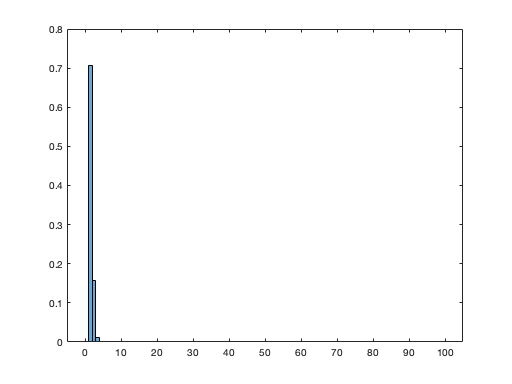

[h_isi_mid] = histcounts(isi_mid,edge_mid,'Normalization','pdf');

% make ISI histogram with all cells, all trials
allspikes = Spikes(fr_row(max_ind),:);
spike_ind = [];
for i = 1:ntrials
    newspikes = allspikes{1,i};
    for j = 1:30
        newspike_ind = find(newspikes(:,j));
        spike_ind = [spike_ind; newspike_ind];
    end
end
isi_bursty = diff(spike_ind);
isi_bursty = isi_bursty(isi_bursty>0);
edge_bursty = 0:100;
histogram(isi_bursty,edge_bursty,'Normalization','pdf')

[h_isi_bursty] = histcounts(isi_bursty,edge_bursty,'Normalization','pdf');

## firing rate rasters

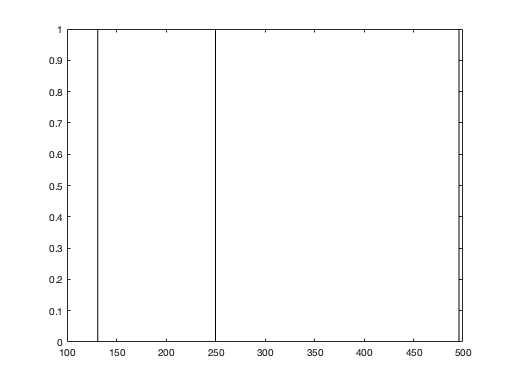

fr_row = find(fr==10,1);
allspikes = Spikes{fr_row,1};
spikes = allspikes(:,1);
spiketimes = find(spikes(5500:6000));
spiketimes = [spiketimes; 250];
% 10 Hz
figure;
for i = 1:length(spiketimes) % index over spike times in trial j
    plot([spiketimes(i) spiketimes(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

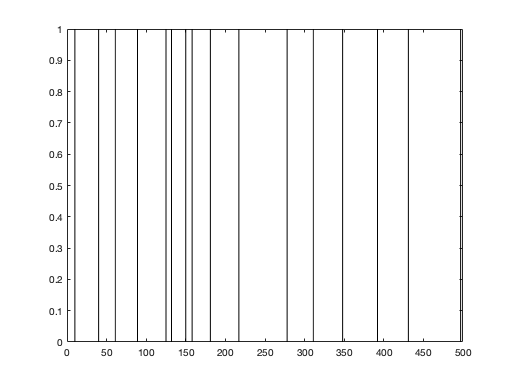


fr_row = find(fr==50,1);
allspikes = Spikes{fr_row,1};
spikes = allspikes(:,1);
spiketimes = find(spikes(4000:4500));
% 50 Hz
figure;
for i = 1:length(spiketimes) % index over spike times in trial j
    plot([spiketimes(i) spiketimes(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

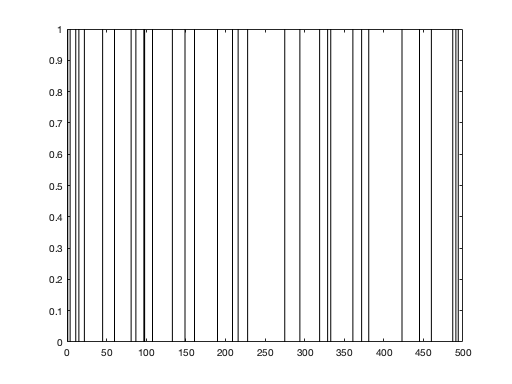


fr_row = find(fr==100,1);
allspikes = Spikes{fr_row,1};
spikes = allspikes(:,1);
spiketimes = find(spikes(3800:4300));
spiketimes = [spiketimes; 1; 4; 15; 22; 460; 487];
% 100 Hz
figure;
for i = 1:length(spiketimes) % index over spike times in trial j
    plot([spiketimes(i) spiketimes(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

## population size rasters

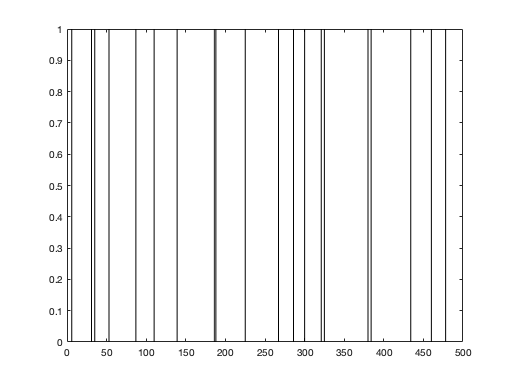

% constant firing rate of 50 Hz, correlation of 0
fr_rows = find(fr==50);
fr_row = fr_rows(5);
allspikes = Spikes{fr_row,1};
spikes = allspikes(:,1);
spiketimes = find(spikes(600:1100));
% N=1
figure;
for i = 1:length(spiketimes) % index over spike times in trial j
    plot([spiketimes(i) spiketimes(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

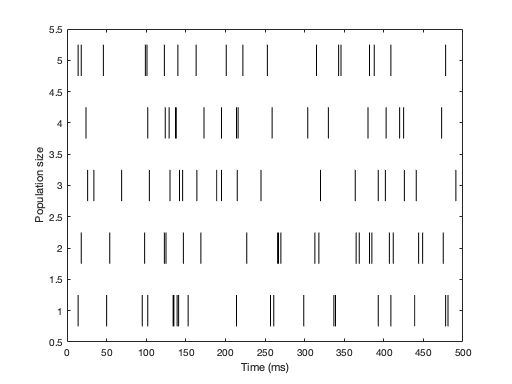


% N = 5;
% for each of the 5 cells, plot the action potentials as ticks
for j = 1:5 % index over cells
    spikes = allspikes(:,j+1);
    spiketimes = find(spikes(500:1000));
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('Population size')

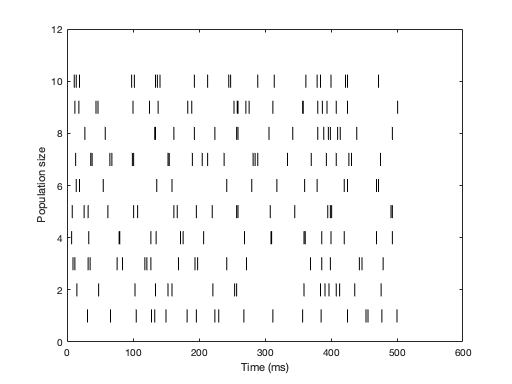


% N = 10;
for j = 1:10 % index over cells
    spikes = allspikes(:,j+6);
    spiketimes = find(spikes(500:1000));
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('Population size')

## correlation rasters

% population size 5, firing rate 50 Hz
% corr = 0
fr_rows = find(fr==50);
fr_row = fr_rows(5);
allspikes = Spikes{fr_row,1};
for j = 1:5 % index over cells
    spikes = allspikes(:,j+1);
    spiketimes = find(spikes(1500:1999));
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('Population size')

% corr = 0.5, fr = 50 Hz
rng(100);
N = 5;
lambda1 = 150;
lambda2 = 10;
k1 = 6;
k2 = 5;
alpha1 = 1;
alpha2 = 0.9;

allspikes = RenewalProcess(N, alpha1, alpha2, lambda1, lambda2, k1, k2);
[allspikes, ~, avgcorr, ~, ~] = RenewalStats(N, allspikes, lambda1, k1);
% can check avgcorr is 0.5
disp(avgcorr)

for j = 1:5 % index over cells
    spikes = allspikes(:,j);
    spiketimes = find(spikes(7600:8100));
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('Population size')

% corr = 1, fr = 50 Hz
alpha1 = 1;
alpha2 = 1;

allspikes = RenewalProcess(N, alpha1, alpha2, lambda1, lambda2, k1, k2);
[allspikes, ~, avgcorr, ~, ~] = RenewalStats(N, allspikes, lambda1, k1);

for j = 1:5 % index over cells
    spikes = allspikes(:,j);
    spiketimes = find(spikes(500:1000));
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('Population size')

## responsivity rasters

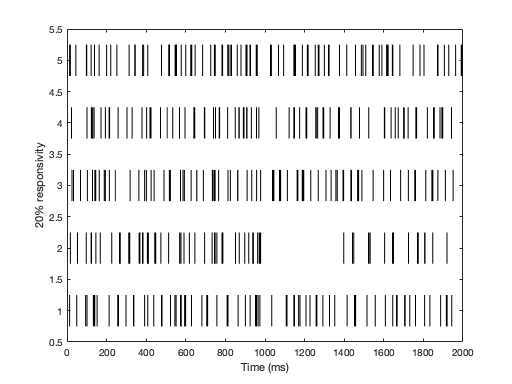

rng(5899);
% constant firing rate of 50 Hz, correlation of 0ish
fr_rows = find(fr==50);
fr_row = fr_rows(5);
allspikes = Spikes{fr_row,1};
params = c(fr_row,11:14);
params = cell2mat(params);

prestimspikes = allspikes(501:1500,2:6);

% simulate 1, 3, and 5 cells responding to the stimulus (with tau = 600)
tau = 600;
poststimspikes = PostStimProcess(tau, 5, 0, 0, params(1), params(2), params(3), params(4));

unresponsivespikes = RenewalProcess(5, 0, 0, params(1), params(2), params(3), params(4));
unresponsivespikes = unresponsivespikes(1:1000,:);

% 1 cell responds (20% responsivity)
% for each of the 5 cells, plot the action potentials as ticks
time_vec = [];
partition = 1:2000;
for j = 1:5 % index over cells
    if j == 2
        spikes = [prestimspikes(:,j); poststimspikes(:,j)];
    else
        spikes = [prestimspikes(:,j); unresponsivespikes(:,j)];
    end
    spiketimes = find(spikes);
    time_vec = [time_vec; spiketimes];
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('20% responsivity')

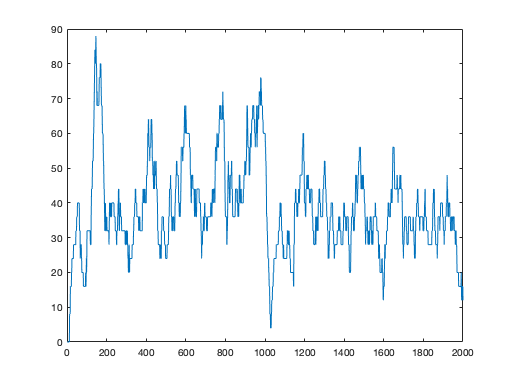

    
r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH1 = filter(h,1,r);
plot(PSTH1)

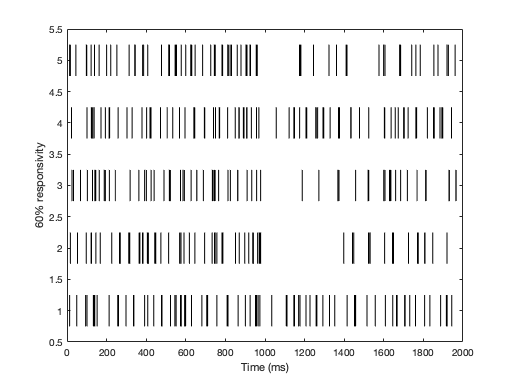


% 3 cells respond (60% responsivity)
% for each of the 5 cells, plot the action potentials as ticks
time_vec = [];
for j = 1:5 % index over cells
    if j == 2 || j==3 || j==5
        spikes = [prestimspikes(:,j); poststimspikes(:,j)];
    else
        spikes = [prestimspikes(:,j); unresponsivespikes(:,j)];
    end
    spiketimes = find(spikes);
    time_vec = [time_vec; spiketimes];
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('60% responsivity')

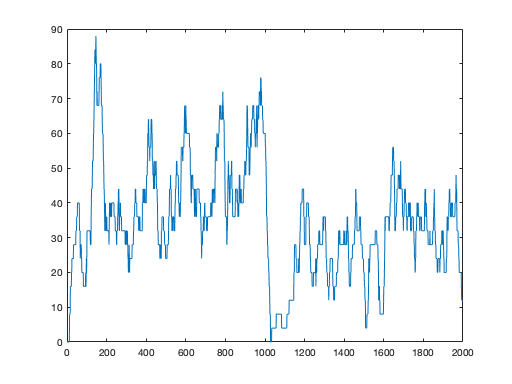


r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH2 = filter(h,1,r);
plot(PSTH2)

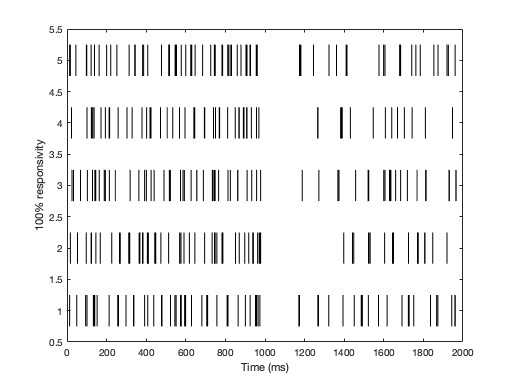


time_vec = [];
% 5 cells respond (100% responsivity)
% for each of the 5 cells, plot the action potentials as ticks
for j = 1:5 % index over cells
    spikes = [prestimspikes(:,j); poststimspikes(:,j)];
    spiketimes = find(spikes);
    time_vec = [time_vec; spiketimes];
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('100% responsivity')

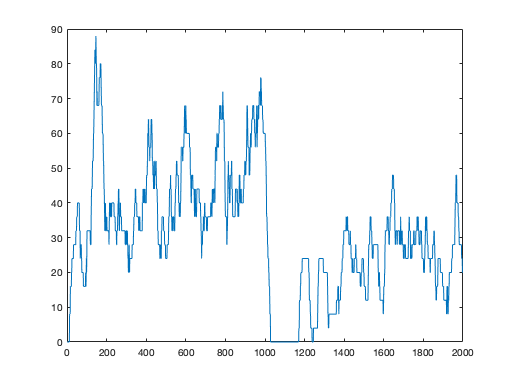


r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH3 = filter(h,1,r);
plot(PSTH3)

## Stimulus

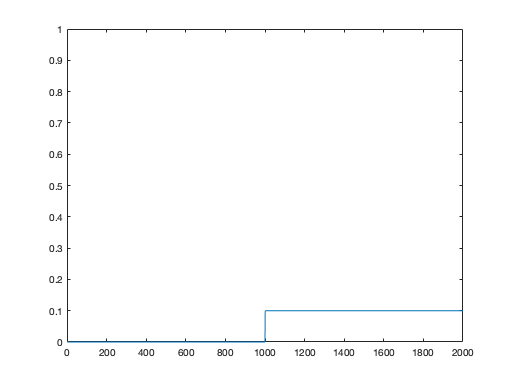

% 3 contrast steps
step1 = [zeros(1000,1); 0.1.*ones(1000,1)];
plot(step1)
ylim([0 1])

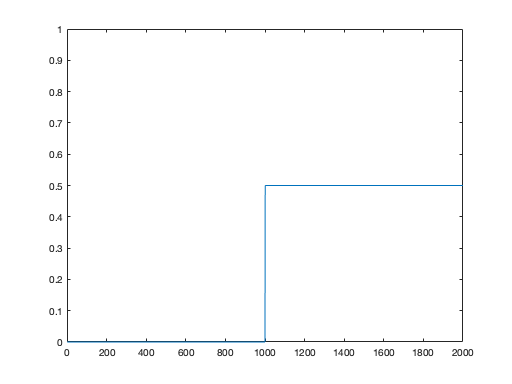


step2 = [zeros(1000,1); 0.5.*ones(1000,1)];
plot(step2)
ylim([0 1])

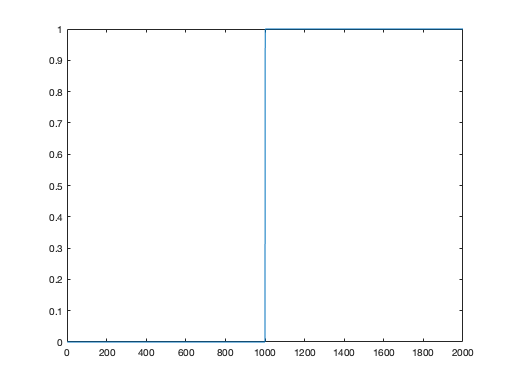


step3 = [zeros(1000,1); ones(1000,1)];
plot(step3)
ylim([0 1])

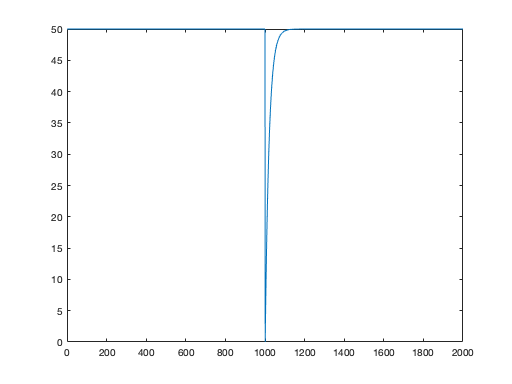

l1 = 50;
tau = 0.001*20; % convert to s
T = 1; % total time (in s) of our generated sequence
dt1 = 0.001; % set interval size = 0.01 s for burst sequence (10 ms precision for bursts)
L = T/dt1; % total length of burst and spike sequences
r = zeros(L,1);
r(1) = 0;
for i = 2:L
    r(i) = r(i-1)+(l1-r(i-1))*dt1/tau;
end
R1 = [l1.*ones(1000,1); r];
plot(R1)

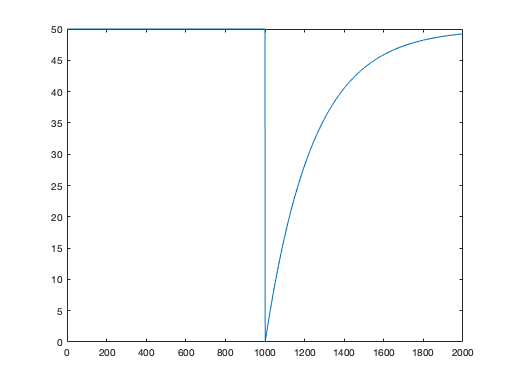



tau = 0.001*240; % convert to s
r = zeros(L,1);
r(1) = 0;
for i = 2:L
    r(i) = r(i-1)+(l1-r(i-1))*dt1/tau;
end
R2 = [l1.*ones(1000,1); r];
plot(R2)

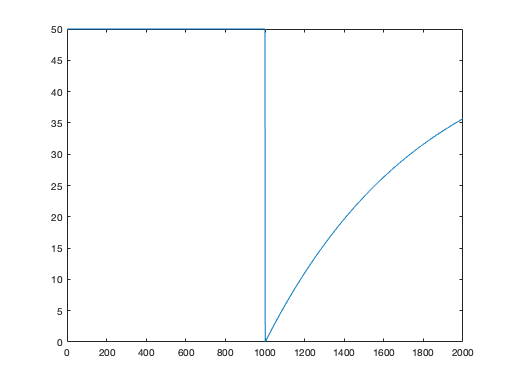



tau = 0.001*800; % convert to s
r = zeros(L,1);
r(1) = 0;
for i = 2:L
    r(i) = r(i-1)+(l1-r(i-1))*dt1/tau;
end
R3 = [l1.*ones(1000,1); r];
plot(R3)

rng(5899);
% constant firing rate of 50 Hz, correlation of 0ish
fr_rows = find(fr==50);
fr_row = fr_rows(5);
allspikes = Spikes{fr_row,1};
params = c(fr_row,11:14);
params = cell2mat(params);

prestimspikes = allspikes(501:1500,2:6);

tau = 20;
poststimspikes1 = PostStimProcess(tau, 5, 0, 0, params(1), params(2), params(3), params(4));

tau = 240;
poststimspikes2 = PostStimProcess(tau, 5, 0, 0, params(1), params(2), params(3), params(4));

tau = 800;
poststimspikes3 = PostStimProcess(tau, 5, 0, 0, params(1), params(2), params(3), params(4));

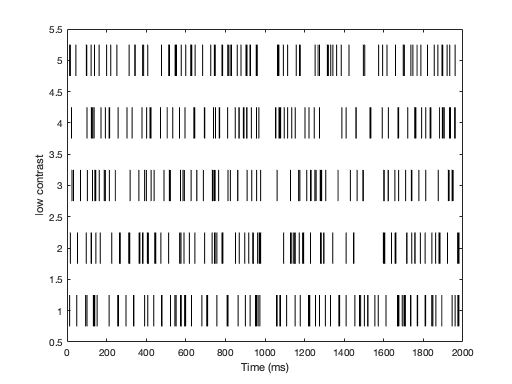

spikes1 = [prestimspikes; poststimspikes1];
for j = 1:5 % index over cells
    spikes = spikes1(:,j);
    spiketimes = find(spikes);
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('low contrast')

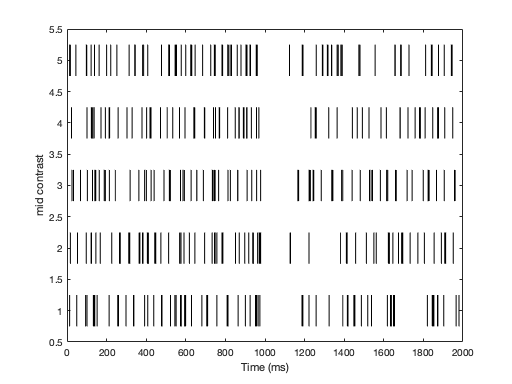

spikes2 = [prestimspikes; poststimspikes2];
for j = 1:5 % index over cells
    spikes = spikes2(:,j);
    spiketimes = find(spikes);
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('mid contrast')

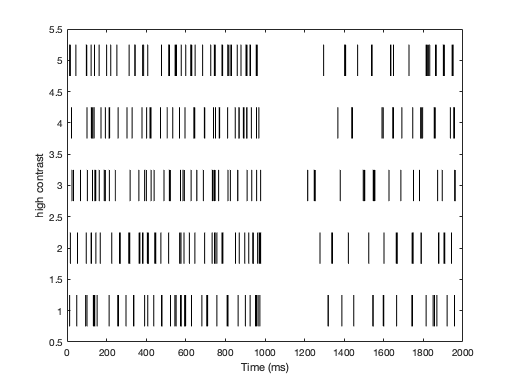

spikes3 = [prestimspikes; poststimspikes3];
for j = 1:5 % index over cells
    spikes = spikes3(:,j);
    spiketimes = find(spikes);
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')
ylabel('high contrast')

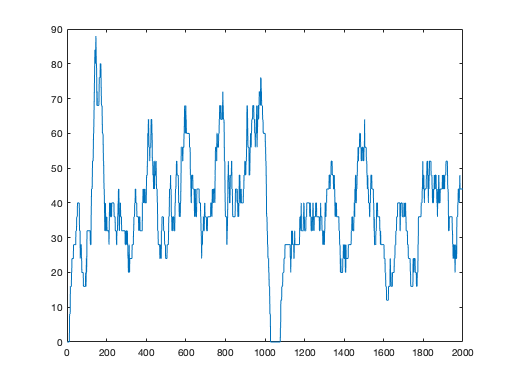

% PSTHs
time_vec = [];
partition = 1:2000;
for j = 1:5
    time_vec = [time_vec; find(spikes1(:,j))];
end
    
r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH1 = filter(h,1,r);
plot(PSTH1)

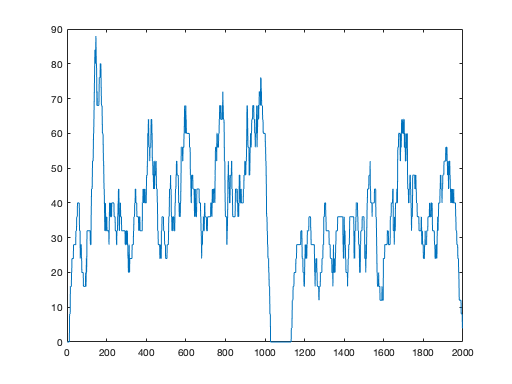

time_vec = [];
for j = 1:5
    time_vec = [time_vec; find(spikes2(:,j))];
end
    
r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH2 = filter(h,1,r);
plot(PSTH2)

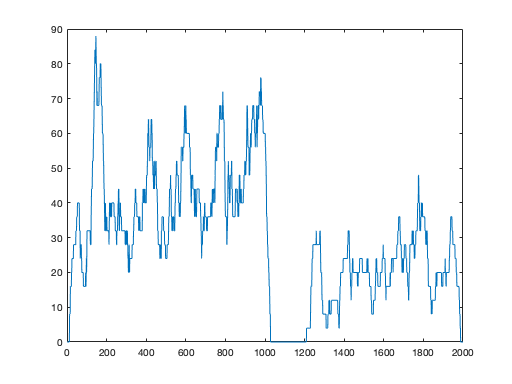

time_vec = [];
for j = 1:5
    time_vec = [time_vec; find(spikes3(:,j))];
end
    
r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/5; % firing rate in bin i, converted to spikes/s
end
t = 50;
h = 1/t.*ones(1,t);
PSTH3 = filter(h,1,r);
plot(PSTH3)

## Pictorial representation of Cox process

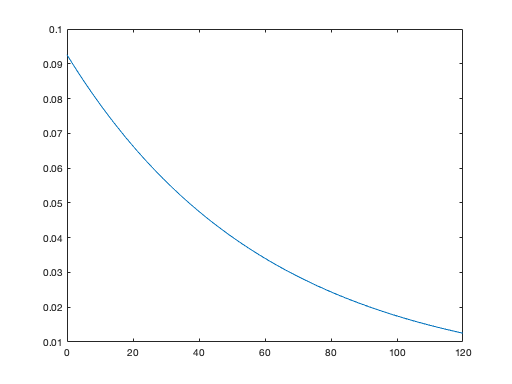

x = 0:120;
y = exppdf(x,60);
y = 5.555.*y;
plot(x,y)

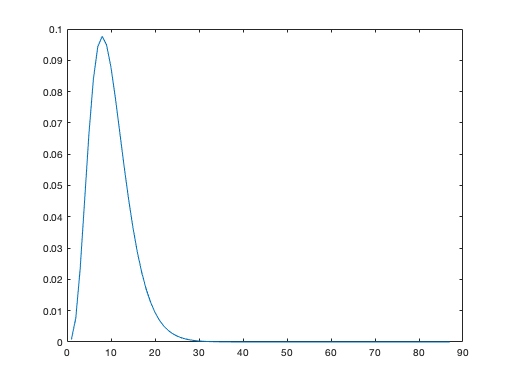

y = gampdf(x,5,2);
plot(x,y)

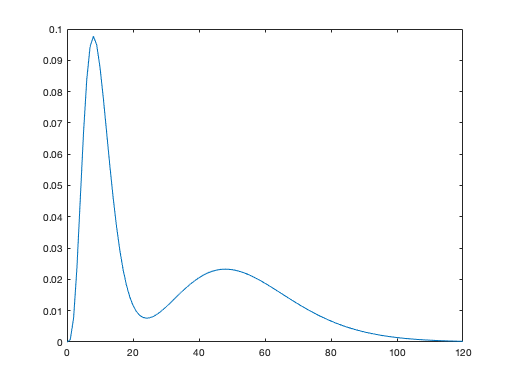

y = gampdf(x,5,2)+gampdf(x,9,6);
plot(x,y)

## justification for sum of gammas fit

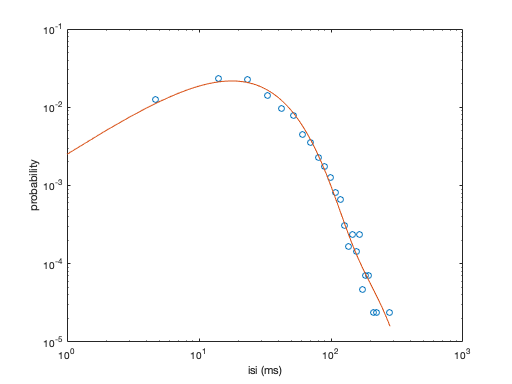

rng(5899);
params = [200 4 4 4];
spikes = RenewalProcess(15, 0, 0, params(1), params(2), params(3), params(4));
spike_ind = [];
for i = 1:15
    spike_ind = [spike_ind; find(spikes)];
end
isi = diff(spike_ind);
isi = isi(isi>0);

% fit with sum of gammas
[c, gof] =  SumGamFit(isi, params(1), params(2), params(3), params(4));
x = 0:max(isi); % range of ISIs (with 1 ms precision)
c1 = 2.^c(x);
[z, edges] = histcounts(isi,30,'Normalization','pdf');
[z1, ~] = histcounts(isi,edges);
avgedges = mean([edges(1:end-1);edges(2:end)]);
loglog(avgedges,z,'o')
hold on
loglog(x,c1)
hold off
xlabel('isi (ms)')
ylabel('probability')

gof.rmse

ans = 0.6192

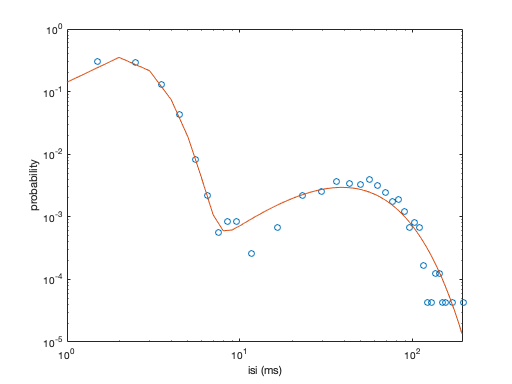

rng(5899);
params = [96 15 6 3];
spikes = RenewalProcess(5, 0, 0, params(1), params(2), params(3), params(4));
spike_ind = [];
for i = 1:5
    spike_ind = [spike_ind; find(spikes)];
end
isi = diff(spike_ind);
isi = isi(isi>0);
% fit with sum of gammas
[c, gof] =  SumGamFit(isi, params(1), params(2), params(3), params(4));
x = 0:max(isi); % range of ISIs (with 1 ms precision)
c1 = 2.^c(x);
edges = [1:10 13.2:6.6:200];
[z, ~] = histcounts(isi,edges,'Normalization','pdf');
avgedges = mean([edges(1:end-1);edges(2:end)]);
loglog(avgedges,z,'o')
hold on
loglog(x,c1)
hold off
xlabel('isi (ms)')
ylabel('probability')

gof.rmse

ans = 0.7272

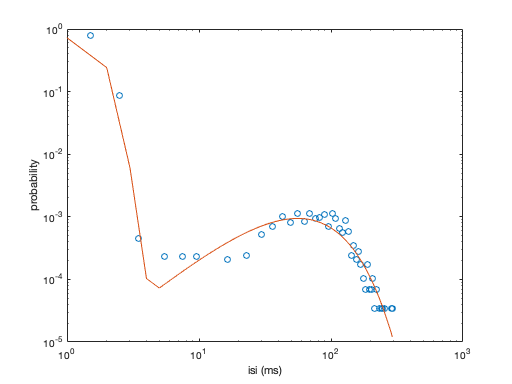

rng(5899);
params = [50 60 5 6];
spikes = RenewalProcess(5, 0, 0, params(1), params(2), params(3), params(4));
spike_ind = [];
for i = 1:5
    spike_ind = [spike_ind; find(spikes)];
end
isi = diff(spike_ind);
isi = isi(isi>0);

% fit with sum of gammas
[c, gof] =  SumGamFit(isi, params(1), params(2), params(3), params(4));
x = 0:max(isi); % range of ISIs (with 1 ms precision)
c1 = 2.^c(x);
edges = [1:10 13.2:6.6:300];
[z, ~] = histcounts(isi,edges,'Normalization','pdf');
[z1, ~] = histcounts(isi,edges);
avgedges = mean([edges(1:end-1);edges(2:end)]);
loglog(avgedges,z,'o')
hold on
loglog(x,c1)
hold off
xlabel('isi (ms)')
ylabel('probability')

gof.rmse

ans = 0.7411

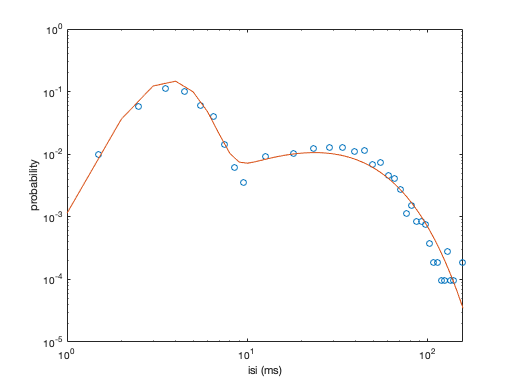

rng(5899);
params = [100 10 4 5];
spikes = RenewalProcess(5, 0, 0, params(1), params(2), params(3), params(4));
spike_ind = [];
for i = 1:5
    spike_ind = [spike_ind; find(spikes)];
end
isi = diff(spike_ind);
isi = isi(isi>0);

% fit with sum of gammas
[c, gof] =  SumGamFit(isi, params(1), params(2), params(3), params(4));
x = 0:max(isi); % range of ISIs (with 1 ms precision)
c1 = 2.^c(x);
edges = [1:10 10:5.3:160];
[z, ~] = histcounts(isi,edges,'Normalization','pdf');
avgedges = mean([edges(1:end-1);edges(2:end)]);
loglog(avgedges,z,'o')
hold on
loglog(x,c1)
hold off
xlabel('isi (ms)')
ylabel('probability')

gof.rmse

ans = 0.7450

## Constructing IT

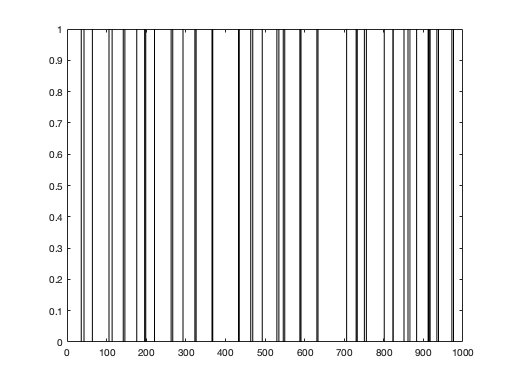

% 1. Generate spikes
rng(5899);
N=1;
alpha1=0; 
alpha2=0; 
lambda1=180; 
lambda2=6;
k1=6;
k2=3;

spikes = RenewalProcess(N, alpha1, alpha2, lambda1, lambda2, k1, k2);
spike_ind = find(spikes(1:1000));
figure;
for i = 1:length(spike_ind) % index over spike times in trial j
    plot([spike_ind(i) spike_ind(i)], [0 1], 'Color', [0 0 0])
    hold on
end
hold off

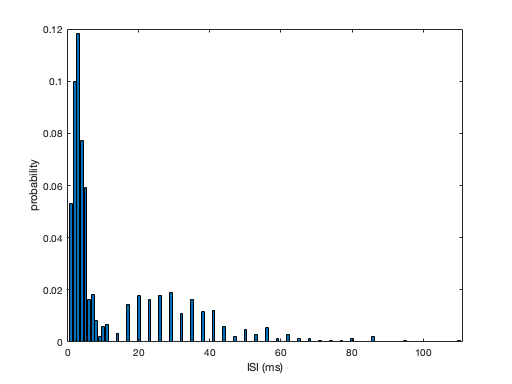

% 2. Compute ISI distribution
spike_ind = find(spikes);
isi = diff(spike_ind);
isi = [spike_ind(1); isi];
edges = [1:10 11:3:max(isi)+1];
meanISI = histcounts(isi, edges, 'Normalization', 'pdf');
X = edges(1:length(edges)-1);
bar(X, meanISI)
xlabel('ISI (ms)')
ylabel('probability')

c = SumGamFit(isi, lambda1, lambda2, k1, k2);

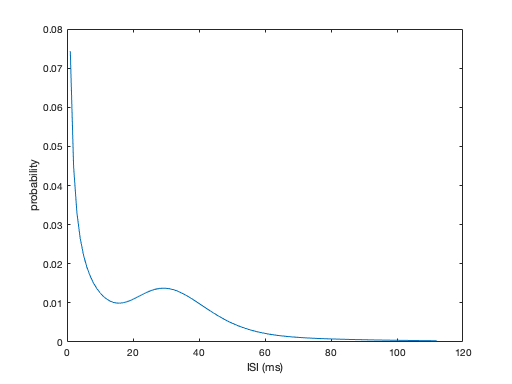

x = 1:max(isi); % range of ISIs (with 1 ms precision)
y = 2.^c(x);
plot(x,y)
xlabel('ISI (ms)')
ylabel('probability')

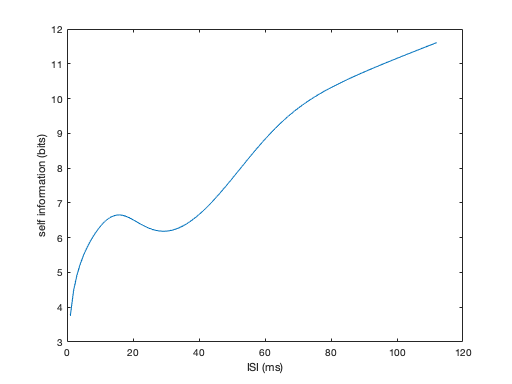

% 3. Self information curve
y = -c(x); % information (-log2(p(x), where c = log2(p))
plot(x,y)
xlabel('ISI (ms)')
ylabel('self information (bits)')

% 4. IT
tau = 600;
poststimspikes = PostStimProcess(tau, N, alpha1, alpha2, lambda1, lambda2, k1, k2);
spikes = [spikes(1:1000); poststimspikes; 1];
spike_ind = find(spikes);
isi = diff(spike_ind);
isi = [spike_ind(1); isi];

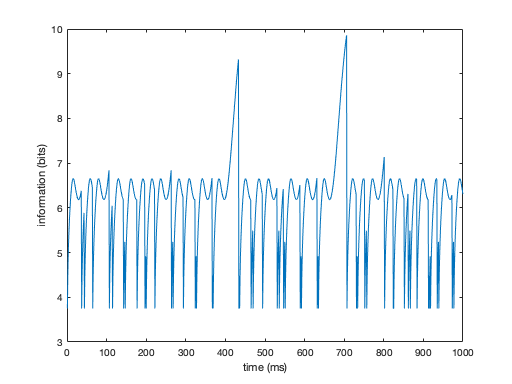

x = 1:max(isi); % range of ISIs (with 1 ms precision)
y = -c(x); % information (-log2(p(x), where c = log2(p))
mininfo = min(y); % baseline 
% by defn, minimum information corresponds with the most frequent ISI value
modeisi_ind = find(y == mininfo);
modeisi = x(modeisi_ind);
modeisi = round(modeisi);
long_x = 1:isi(1);
nothing = ones(1,modeisi-1)*mininfo;
[~, this_x] = min(abs(x-isi(1)));
something = y(modeisi_ind:this_x);
chunk = [nothing something.'];
chunk = reshape(chunk,1,[]);
long_y = chunk;

IT = [];
short_x = [];
short_y = [];
mode_x = [];
mode_y = [];
for i = 2:length(isi)
    this_isi = isi(i);
    if this_isi == modeisi
        chunk = ones(1, this_isi)*mininfo;
        chunk = reshape(chunk,1,[]);
        mode_x = [mode_x 1+sum(isi(1:i-1)):sum(isi(1:i))];
        mode_y = [mode_y chunk];
    elseif this_isi > modeisi
        nothing = ones(1,modeisi-1)*mininfo;
        [~, this_x] = min(abs(x-this_isi));
        something = y(modeisi_ind:this_x);
        chunk = [nothing something.'];
        chunk = reshape(chunk,1,[]);
        long_x = [long_x 1+sum(isi(1:i-1)):sum(isi(1:i))];
        long_y = [long_y chunk];
    elseif this_isi < modeisi
        nothing = ones(1,this_isi-1)*mininfo;
        [~, this_x] = min(abs(x-this_isi));
        something = y(this_x);
        chunk = [nothing something.'];
        chunk = reshape(chunk,1,[]);
        short_x = [short_x 1+sum(isi(1:i-1)):sum(isi(1:i))];
        short_y = [short_y chunk];
    end
    
    IT = [IT chunk];  
end

IT = InfoTrain(c, isi);
IT = IT(1:2000);
IT(end) = min(IT);

plot(IT(1:1000))
xlabel('time (ms)')
ylabel('information (bits)')

## Many cells

% 1. Generate spikes
rng(5899);
N=5;
alpha1=0.8; %0
alpha2=0; 
lambda1=100; %30 %120
lambda2=15;
k1=3; %3 %6
k2=5;
spikes_prestim = RenewalProcess(N, alpha1, alpha2, lambda1, lambda2, k1, k2);

% 2. fit isi dist to sum of gammas
C = cell(1,N);
for i = 1:N
    spikeind = find(spikes_prestim(:,i));
    isi = diff(spikeind);
    c = SumGamFit(isi, lambda1, lambda2, k1, k2);
    C{i} = c;
end

tau = 600;
spikes_poststim1 = PostStimProcess(tau, N-1, alpha1, alpha2, lambda1, lambda2, k1, k2);
spikes_poststim2 = RenewalProcess(1, alpha1, alpha2, lambda1, lambda2, k1, k2);
spikes_poststim2 = spikes_poststim2(1:1000,:);
spikes_poststim = [spikes_poststim1 spikes_poststim2];
spikes = [spikes_prestim; spikes_poststim; ones(1,N)];

% population information train
iIT = zeros(11001,N);
for i = 1:N
    spikeind = find(spikes(:,i));
    isi = diff(spikeind);
    isi = [spikeind(1); isi];
    iIT(:,i) = InfoTrain(C{i}, isi);
end
IT = sum(iIT, 2);
optimal_thresh = max(IT(1:10000));
[~, reactiontime, gaplength] = Performance(IT, optimal_thresh)

reactiontime = 31.6458

gaplength = 60.9444

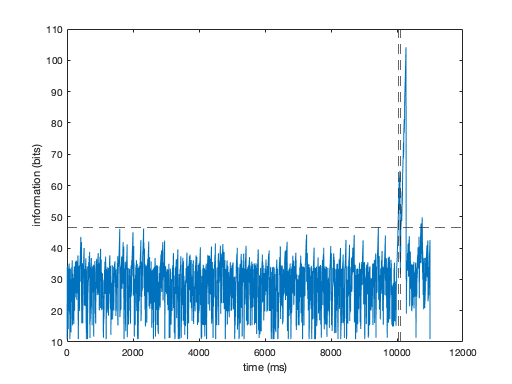


plot(IT)
hold on
yline(optimal_thresh,'--')
hold on
xline(reactiontime+10000, '--')
hold on
xline(reactiontime+10000+gaplength, '--')
hold off
xlabel('time (ms)')
ylabel('information (bits)')

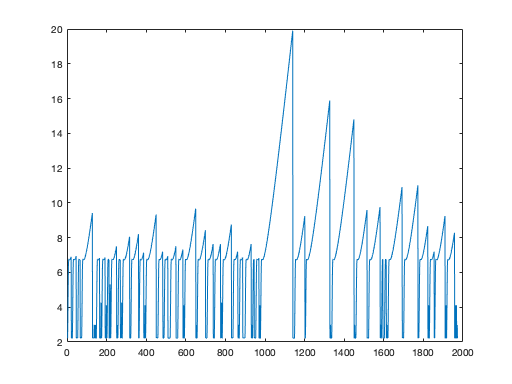

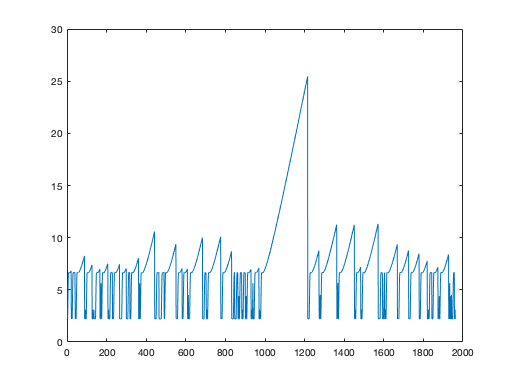

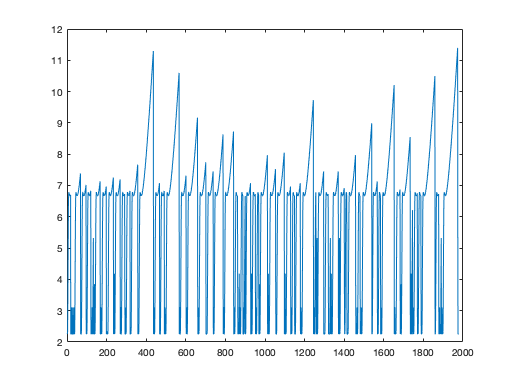

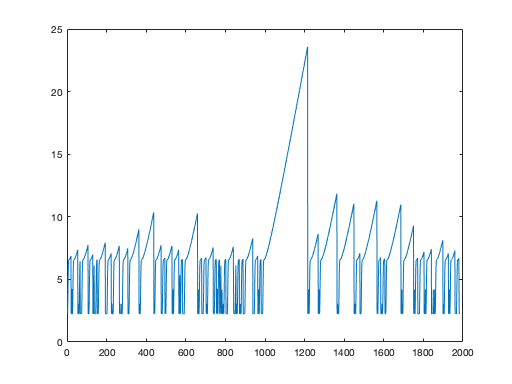

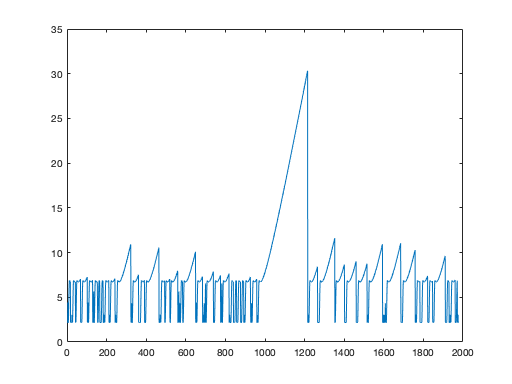

% plot individual information trains
for i = 1:N
    figure;
    spikeind = spike_ind{i};
    isi = diff(spikeind);
    isi = [spikeind(1); isi];
    this_iIT = InfoTrain(C{i}, isi);
    plot(this_iIT)
end

% population PSTH
partition = 1:11001;
time_vec = [];
for j = 1:N
    time_vec = [time_vec; find(spikes(:,j))];
end
r = zeros(1, length(partition));
for k = 1:length(partition)
    r(k) = 1000.*length(find(time_vec == partition(k)))/N; % firing rate in bin i, converted to spikes/s
end
t = 32;
h = 1/t.*ones(1,t);
PSTH = filter(h,1,r);
[reactiontime, gaplength] = FRModelPerformance(PSTH)

reactiontime = 16

gaplength = 51

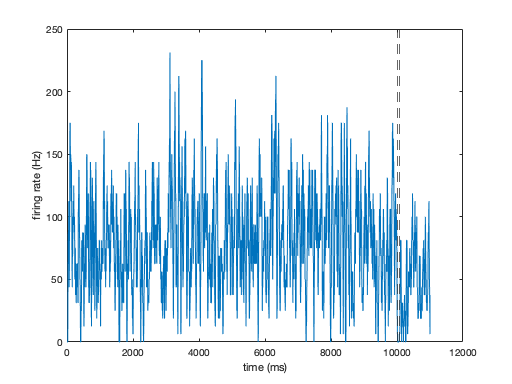


plot(PSTH)
hold on
xline(reactiontime+10000, '--')
hold on
xline(reactiontime+10000+gaplength, '--')
hold off
xlabel('time (ms)')
ylabel('firing rate (Hz)')

PSTH(11000) = PSTH(11001);
PSTH = PSTH.';
time = 1:11001;
time = time./1000;

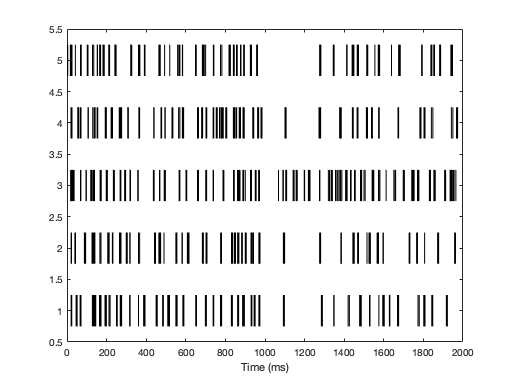

spikes11 = spikes(:,[1 2 5 4 3]);
for j = 1:5 % index over cells
    spikes1 = spikes11(9000:11000,j);
    spiketimes = find(spikes1);
    for i = 1:length(spiketimes)
       plot([spiketimes(i) spiketimes(i)], [j-0.25 j+0.25], 'Color', [0 0 0])
       hold on  
    end
end
hold off
xlabel('Time (ms)')

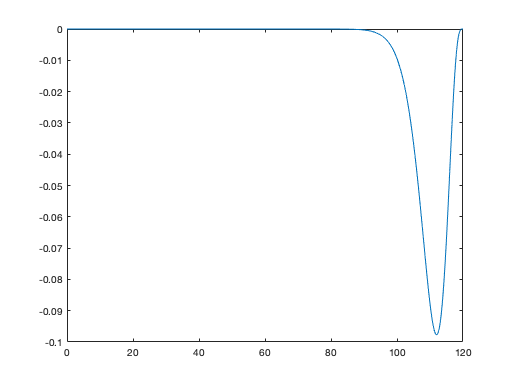

% generate generic fake signal
x = 0:0.001:120;
y = gampdf(x,5,2);
y1 = -1.*y;
y1 = flip(y1);
plot(x,y1)